% Input signal
y = [0, 2, 4, 3, 1, 5];
time = [0, 1, 2, 3, 4, 5];

% Sampling rate
fs = 10;

% Generate ZOH signal
t_zoh = 0:1/fs:max(time);
y_zoh = interp1(time, y, t_zoh, 'previous');

% Add new values to the end of the signal
y_extended = [y, 6, 8, 7, 8, 9, 10, 11];
%%time_extended = [time, max(time)+1, max(time)+2, max(time)+3];
for i=1:length(y_extended)
    time_extended(i) = i;
end
y_extended = y_extended(2:length(y_extended))

y_extended =      2     4     3     1     5     6     8     7     8     9    10    11


time_extended = time_extended(2:length(time_extended))

time_extended =      2     3     4     5     6     7     8     9    10    11    12    13


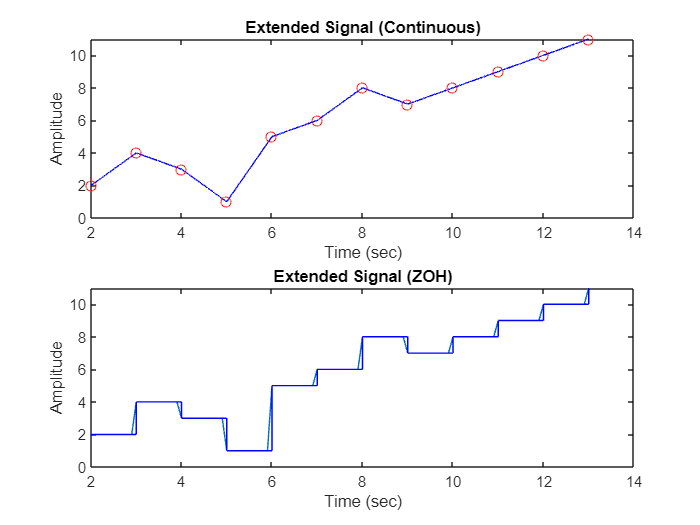



% Plot extended signal
t_cont_ext = 0:0.001:max(time_extended);
y_cont_ext = interp1(time_extended, y_extended, t_cont_ext, 'linear');

figure;
subplot(2,1,1);
plot(t_cont_ext, y_cont_ext, 'b-', time_extended, y_extended, 'ro');
title('Extended Signal (Continuous)');
xlabel('Time (sec)');
ylabel('Amplitude');

t_zoh_ext = 0:1/fs:max(time_extended);
y_zoh_ext = interp1(time_extended, y_extended, t_zoh_ext, 'previous');

subplot(2,1,2);
plot(t_zoh_ext, y_zoh_ext, t_cont_ext, interp1(t_zoh_ext, y_zoh_ext, t_cont_ext, 'previous'), 'b-');
title('Extended Signal (ZOH)');
xlabel('Time (sec)');
ylabel('Amplitude');